## Description:

architecture: 10 bat, 9 + 3 conv

BCV N * 4N+2

CCVs n-1 * 4N + 2, only 3 lines nonzero

CCVd n-1 * 4n+2

LCM N * 4N+2

## modulation of signal

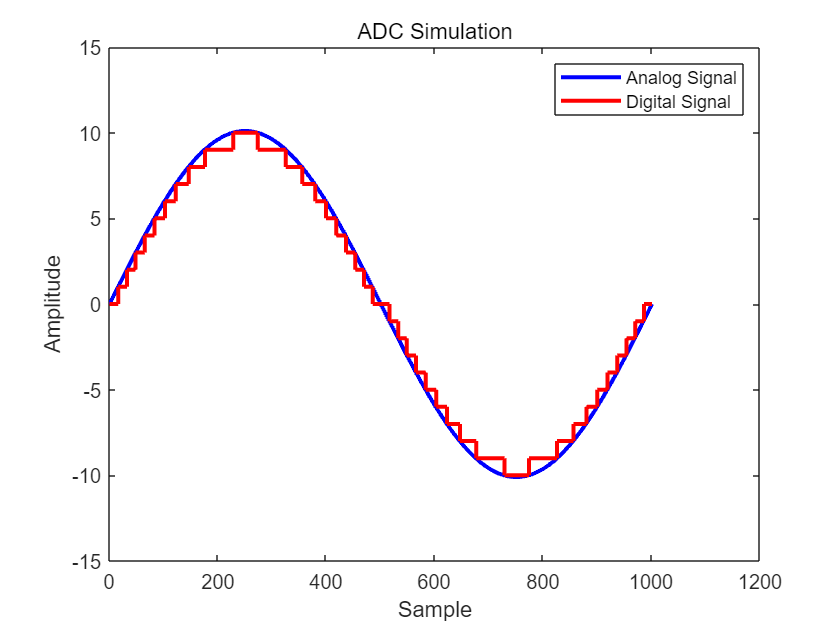

% Parameters
f = 100e3;

n_bat = 10;
n_v_level = 2 * n_bat + 1;
n_t = 4 * n_bat + 2;


V_ref = n_bat;              % Reference voltage (e.g., 5V)
num_samples = 1000;     % Number of samples to convert

% Generate analog input signal
t = linspace(0,1/f,num_samples + 1);
dt = 1/num_samples;

analog_signal = V_ref * 1.01 * sin(2*pi*f*t);

% Simulate quantization (ADC conversion)
digital_signal = quantize(analog_signal, n_bat, V_ref);
% Plot the analog and digital signals
plot(analog_signal, 'b', 'LineWidth', 2);
hold on;
stairs(digital_signal, 'r', 'LineWidth', 2);
hold off;
xlabel('Sample');
ylabel('Amplitude');
title('ADC Simulation');
legend('Analog Signal', 'Digital Signal');


delta_t = zeros(1,n_t);
output = zeros(1,n_t);
for i = 1: ceil(n_t/4)
    value = (i - 1) * V_ref / n_bat;
    indices = find(digital_signal(1:length(digital_signal)/4) == value);
    if i ~= ceil(n_t/4)
        delta_t(i) = dt * (max(indices) - min(indices));
        delta_t(2 * n_bat + 2 - i) = delta_t(i);
        delta_t(2 * n_bat + 1 + i) = delta_t(i);
        delta_t(4 * n_bat + 3 - i) = delta_t(i);
        output(i) = value;
        output(2 * n_bat + 2 - i) = output(i);
        output(2 * n_bat + 1 + i) = -output(i);
        output(4 * n_bat + 3 - i) = -output(i);
    else
        delta_t(i) = 2 * dt * (max(indices) - min(indices));
        delta_t(2 * n_bat + 1 + i) = delta_t(i);
        output(i) = value;
        output(2 * n_bat + 1 + i) = -output(i);
    end
end

delta_t = delta_t / sum(delta_t);
size(delta_t)

ans =      1    42


## architecture

global SYS TEST;
% create 10 batteries, 10 HB, 1 bus 
for i = 1:10
    Input{i} =  struct('sn','bat_1','ind',i,'volt',1,'ohmres',0.01,...
       'curlim',1,'curlim_var',0.2,'curlim_mu',1,... % current lim,hete
       'res',0.001,'res_mu',0.003,'res_var',0.001/3,...
       'qlim',1,'qlim_mu',1,'qlim_var',0.2,...% electric charge
       'eloss_coeff',0.12,'eloss_coeff_mu',0.12,'eloss_coeff_var',0.012);  % propotional for power process
end
Input{end+1} = struct('sn','bus1','ind',1,'volt',1,'curlim',-1); % index 10


## simulation parameters

% User Input end
% % TESTironment
% % simulation parameters
TEST = struct('Constraint',[],'Sweep',[],'Avg_Conv',[],'Var_Conv',[]);   % Initialize the TESTironment
TEST.Constraint.lambda = 0.3;
TEST.Sweep.Stat.Conv = 5;    % number of var converter power limit to sweep
TEST.Sweep.Stat.Bat = 4;     % number of battery types to sweep 
TEST.Sweep.Conv.p_lim = linspace(0.001,0.2,TEST.Sweep.Stat.Conv);% 
TEST.Sweep.Conv.e_lim = linspace(0.005,0.05,TEST.Sweep.Stat.Conv);%
% % layer 1 - SPARSE
% TEST.Avg_Conv.Num = 3;      % the upper num lim of averaging converter
% TEST.Avg_Conv.ActNum = 3;   % the actural num of averaging converter can be <= the num lim of averaging converter, becuase some of them does not deliver power
% TEST.Avg_Conv.p_lim_vec = 100*ones(1,TEST.Avg_Conv.Num);  % the upper power lim of averaging converter
% TEST.Avg_Conv.e_lim_vec = 100*ones(1,TEST.Avg_Conv.Num);  % the upper power lim of averaging converter
% layer 2 - DENSE
TEST.Var_Conv.Num = 9;       % the upper num lim of var converter
TEST.Var_Conv.p_lim_singlevar = 1;   % the upper power lim of var converter, all var converters have the same power limit
TEST.Var_Conv.e_lim_singlevar = 1;   % the upper power lim of var converter, all var converters have the same power limit
TEST.Var_Conv.MC_trial = 2;  % takes 1 hours
% Categorize the Component lists into Batteries, Cpacitors and Buses
SYS = struct('Bat',[],'Cap',[],'Bus',[],'Conn',[],'Stat',[]);   % Initialize the compoennt list struct
for i = 1:size(Input,2)
    Input{i}.ind = i;  % updated order is bat, bus and cap
    if strcmp(Input{i}.sn(1:3),'bat')
        SYS.Bat{end+1} = Input{i};
    elseif strcmp(Input{i}.sn(1:3),'bus')
        SYS.Bus{end+1} = Input{i};
    elseif strcmp(Input{i}.sn(1:3),'cap')
        SYS.Cap{end+1} = Input{i};
    else
        fprintf('Error in input\n');
        pause;
    end
end
SYS.Stat.Bat_num = size(SYS.Bat,2);
SYS.Stat.Cap_num = size(SYS.Cap,2);
SYS.Stat.Bus_num = size(SYS.Bus,2);
SYS.Stat.Node_num = size(SYS.Bat,2);
SYS.Stat.Delta_t_num = size(delta_t,2);
SYS.Stat.Delta_t = delta_t;
SYS.Stat.Output = output;
for i = 1:SYS.Stat.Cap_num   %Initialize the capactior votlages
    SYS.Cap{i}.volt = Inf;  
end
% Report the Component lists
fprintf('%d%s\n%d%s\n%d%s\n',size(SYS.Bat,2),' Batteries',size(SYS.Cap,2),' SuperCapacitors',size(SYS.Bus,2),' Buses');

10 Batteries
0 SuperCapacitors
1 Buses


for i = 1:SYS.Stat.Bat_num
    TEST.Sweep.Bat{i}.curlim_mu = linspace(2,2,TEST.Sweep.Stat.Bat); % number of battery types to sweep 
    TEST.Sweep.Bat{i}.curlim_var = linspace(0.1,0.4,TEST.Sweep.Stat.Bat);
    TEST.Sweep.Bat{i}.res_mu = linspace(0,0,TEST.Sweep.Stat.Bat);
    TEST.Sweep.Bat{i}.res_var = linspace(0,0,TEST.Sweep.Stat.Bat);
end

I_B = zeros(n_bat,n_t); % battery charge
I_C_s = zeros(n_bat-1,n_t); % sparse converter charge
I_C_d = zeros(n_bat-1,n_t); % dense converter charge
I_L = zeros(n_bat, n_t); % load charge


% if i- j has conn, p(i,j) = 1
P_diff_var_mat_in = zeros(SYS.Stat.Bat_num, SYS.Stat.Bat_num);
P_diff_var_mat_in(SYS.Bat{1}.ind, SYS.Bat{2}.ind) = 1;
P_diff_var_mat_in(SYS.Bat{2}.ind, SYS.Bat{3}.ind) = 1;
P_diff_var_mat_in(SYS.Bat{3}.ind, SYS.Bat{4}.ind) = 1;
P_diff_var_mat_in(SYS.Bat{4}.ind, SYS.Bat{5}.ind) = 1;
P_diff_var_mat_in(SYS.Bat{5}.ind, SYS.Bat{6}.ind) = 1;
P_diff_var_mat_in(SYS.Bat{6}.ind, SYS.Bat{7}.ind) = 1;
P_diff_var_mat_in(SYS.Bat{7}.ind, SYS.Bat{8}.ind) = 1;
P_diff_var_mat_in(SYS.Bat{8}.ind, SYS.Bat{9}.ind) = 1;
P_diff_var_mat_in(SYS.Bat{9}.ind, SYS.Bat{10}.ind) = 1;
P_diff_var_mat_in

P_diff_var_mat_in =      0     1     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0


%P_diff_var_mat_in(SYS.Bat{9}.ind, SYS.Cap{1}.ind) = 1;
% the traditional DPP architectures
%User Input end

SYS.Conn.diff_var = P_diff_var_mat_in;
SYS.Conn.diff_avg = zeros(SYS.Stat.Bat_num, SYS.Stat.Bat_num);
save('SYS','SYS');
save('TEST','TEST');

%% Task 1 Power Design Sparse Layer Converters
clear;
load('TEST');
load('SYS');
TEST1 = TEST;
TEST1.Avg_Conv.trial_num = 10000;  % the numer of random searches to find the optimal placement of averaging converter
TEST1.Avg_Conv.partition = 1; % how to partition the layer 1 converters to achieve the economic of scales
% partition the averaging converter into groups  
% Energy Design Average Converters
% if (isfile('OptAvg_7e.mat'))&&(isfile('OptAvg_5e.mat'))&&(isfile('OptAvg_3e.mat'))
if (isfile('OptAvg_3e.mat'))
    u_in = input('To Save Time, We can Use the Previous 3/5/7 Avg Conv for Var Converter Design, type 1(Y)/0(N): ');
    if (u_in == 1)
%         load('OptAvg_7.mat'); 
%         load('OptAvg_5.mat'); 
        load('OptAvg_3e.mat');
    else
        fprintf('No Previous Ave Conv Design, Need Spend Time to Design Avg Conv, Check the TEST to make sure the setting\n');
        OptAvg_energy = func_average_converter_energy_design(SYS,TEST1);
    end
else
    tic
    OptAvg_energy = func_average_converter_power_design(SYS,TEST1);
    toc
end

无法识别的字段名称 "Num"。

出错 func_average_converter_power_design (第 4 行)
converter_num = ENV.Avg_Conv.Num;

% postprocessing: sort the converter rating in ascending orders
[OptAvg_energy.Conv_energy_rating_partition, OptAvg_energy.Conv_energy_rating_partition_mat] ...
    = func_rating_partition(abs(OptAvg_energy.Avg_energy_flow), TEST4.Avg_Conv.partition); 
% postprocessing: update the primary converter design results to TEST4
TEST4.Avg_Conv.e_lim_vec = OptAvg_energy.Conv_energy_rating_partition;
TEST4.Avg_Conv.e_lim_mat = OptAvg_energy.Conv_energy_rating_partition_mat;
TEST4.Avg_Conv.ActNum = sum(sum(OptAvg_energy.Conv_energy_rating_partition_mat > 0))/2;

fprintf('The battery utilization is\n');    % ~75%
TEST4.Avg_Conv.bat_uratio = abs(OptAvg_energy.output_energy)/sum(OptAvg_energy.Bat_energy_rating);
TEST4.Avg_Conv.bat_uratio
fprintf('The Energy Utilization ratio of the Average Converters\n');  % ~100%
TEST4.Avg_Conv.energy_uratio = sum(sum(abs(OptAvg_energy.Avg_energy_flow)))/sum(sum(TEST4.Avg_Conv.e_lim_mat));
TEST4.Avg_Conv.energy_uratio
% for i = 1:SYS.Stat.Bat_num
%     TEST4.Sweep.Bat{i}.eloss_coeff_mu = linspace(0.12,0.12,TEST4.Sweep.Stat.Bat);
%     TEST4.Sweep.Bat{i}.eloss_coeff_var = linspace(0.002,0.012,TEST4.Sweep.Stat.Bat);
% end
save('OptAvg_3e','OptAvg_energy');
save('TEST4','TEST4');


% Task 2 only diff converters
%% Task 1 Power Design Sparse Layer Converters
clear;
load('TEST');
load('SYS');
TEST2 = TEST;

TEST2.Sweep.Stat.Bat = 8;       % number of battery types to sweep 
TEST2.Sweep.Bat_power_sum = 0;
for i = 1:SYS.Stat.Bat_num
    TEST2.Sweep.Bat{i}.curlim_mu = linspace(1,1,TEST2.Sweep.Stat.Bat);
    TEST2.Sweep.Bat{i}.curlim_var = [0.05, 0.1, 0.15, 0.2, 0.25, 0.5,0.75, 1]; % qlim-Capacity Variation
    TEST2.Sweep.Bat_power_sum = TEST2.Sweep.Bat_power_sum + TEST2.Sweep.Bat{i}.curlim_mu(1);
end
TEST2.Sweep.Stat.Conv = 20;  % number of converter power limits to sweep

TEST2.Sweep.Conv.p_lim = linspace(0.1,1,10)*TEST2.Sweep.Bat_power_sum/TEST2.Var_Conv.Num;


% % TEST2.Sweep.Conv.e_lim = linspace(0,1,TEST2.Sweep.Stat.Conv);
TEST2.Sweep.Stat.Conv = length(TEST2.Sweep.Conv.p_lim);

TEST2.Var_Conv.MC_trial = 100;  % (originally 100)
tic
ExpRes2 = func_dense_converter_power_design(SYS,TEST2); %k0,k1,k2,:
toc

save('ExpRes2','ExpRes2');
save('TEST2','TEST2');

function digital_signal = quantize(analog_signal, n_bat, V_ref)
    % Calculate LSB (Least Significant Bit)
    v_level = V_ref / n_bat;
    temp_signal =  fix(analog_signal / v_level) * v_level;
    correction = 1;% / max(temp_signal);
    digital_signal = temp_signal * correction;   
end